data = readtable('./ai4i2020.csv');


disp(head(data));

    UDI    ProductID     Type     AirTemperature_K_    ProcessTemperature_K_    RotationalSpeed_rpm_    Torque_Nm_    ToolWear_min_    MachineFailure    TWF    HDF    PWF    OSF    RNF
    ___    __________    _____    _________________    _____________________    ____________________    __________    _____________    ______________    ___    ___    ___    ___    ___

     1     {'M14860'}    {'M'}          298.1                  308.6                    1551               42.8             0                0           

% Check for missing values
missing_summary = sum(ismissing(data));

% Fill missing numeric values Median
numeric_cols = {'AirTemperature_K_', 'ProcessTemperature_K_', 'RotationalSpeed_rpm_', 'Torque_Nm_', 'ToolWear_min_'};
for col = numeric_cols
    data.(col{1}) = fillmissing(data.(col{1}), 'movmedian', 10);
end

% Fill categorical with Mode
if sum(ismissing(data.Type)) > 0
    data.Type = fillmissing(data.Type, 'constant', 'M');
end

% 1. Temperature difference (Process - Air)
data.TempDiff_K_ = data.ProcessTemperature_K_ - data.AirTemperature_K_;

% 2. Power (Torque * Rotational Speed / 9.5488 to convert to Watts)
data.Power_W_ = (data.Torque_Nm_ .* data.RotationalSpeed_rpm_) / 9.5488;

% Convert 'Type' (M/L) to numeric (0/1) (1 for 'M', 0 for 'L')
data.Type_encoded = double(strcmp(data.Type, 'M'));

% Z-score normalization
numeric_cols_to_normalize = [numeric_cols, {'TempDiff_K_', 'Power_W_'}];
for col = numeric_cols_to_normalize
    data.(col{1}) = normalize(data.(col{1}));
end

% Separate features (X) and target (y)
X = data(:, {'AirTemperature_K_', 'ProcessTemperature_K_', 'RotationalSpeed_rpm_', ...
                    'Torque_Nm_', 'ToolWear_min_', 'TempDiff_K_', 'Power_W_', 'Type_encoded'});

y = data.MachineFailure;

data_cleaned = removevars(data, {'UDI', 'ProductID', 'Type'});

% Feature and Target values
X_mat = table2array(X);
y_vec = data.MachineFailure;

% Dataset Split to 70% training, 30% testing

cv = cvpartition(y_vec, 'HoldOut', 0.3); 
X_train = X_mat(training(cv), :);
y_train = y_vec(training(cv));
X_test  = X_mat(test(cv), :);
y_test  = y_vec(test(cv));

**Linear SVM Model**

% Linear SVM Model
disp('Linear SVM Model');

Linear SVM Model


svm_model = fitcsvm(X_train, y_train, ...
    'KernelFunction', 'linear', ...
    'Standardize', false, ...
    'BoxConstraint', 1, ...
    'ClassNames', [0 1]);      

% Prediction
y_pred = predict(svm_model, X_test);

% Confusion Matrix
C = confusionmat(y_test, y_pred);
disp(C);

        2898           0
         102           0




% Accuracy
accuracy = sum(y_pred == y_test) / numel(y_test);
fprintf('Test Accuracy: %.2f%%\n\n\n', accuracy * 100);

Test Accuracy: 96.60%




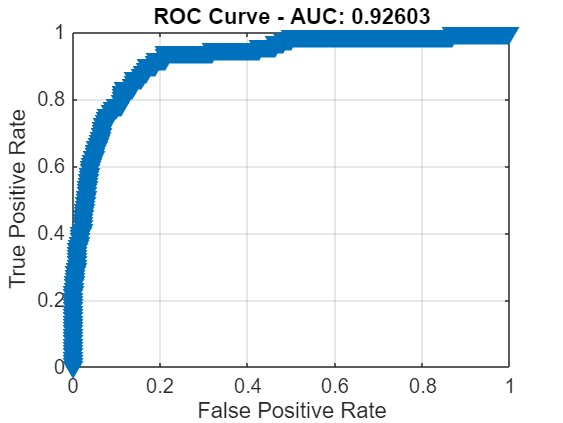


% ROC Curve
[~, scores] = predict(svm_model, X_test);
[Xroc, Yroc, T, AUC] = perfcurve(y_test, scores(:,2), 1);

% Plot ROC
figure;
plot(Xroc, Yroc, 'v-', 'LineWidth', 2);
grid on;
xlabel('False Positive Rate'); 
ylabel('True Positive Rate');
title(['ROC Curve - AUC: ', num2str(AUC)]);

**Non-Linear SVM Model**

% Non-Linear SVM Model
disp('Non-linear SVM Model');

Non-linear SVM Model


non_linear_svm_model = fitcsvm(X_train, y_train, ...
    'KernelFunction', 'rbf', ...
    'Standardize', false, ...
    'BoxConstraint', 1, ...
    'KernelScale', 'auto', ...
    'ClassNames', [0 1]);

% Prediction
y_pred = predict(non_linear_svm_model, X_test);

% Confusion Matrix
C = confusionmat(y_test, y_pred);
disp(C);

        2893           5
          63          39




% Accuracy
accuracy = sum(y_pred == y_test) / numel(y_test);
fprintf('Test Accuracy (RBF SVM): %.2f%%\n\n\n', accuracy * 100);

Test Accuracy (RBF SVM): 97.73%




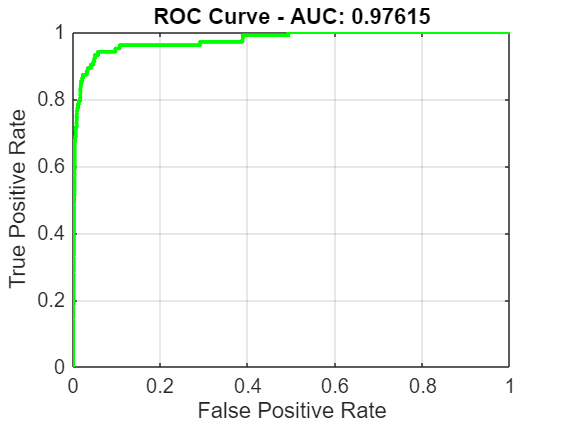


% ROC Curve
[~, scores] = predict(non_linear_svm_model, X_test);
[Xroc, Yroc, T, AUC] = perfcurve(y_test, scores(:,2), 1);

% Plot ROC
figure;
plot(Xroc, Yroc, 'g-', 'LineWidth', 2);
grid on;
xlabel('False Positive Rate'); 
ylabel('True Positive Rate');
title(['ROC Curve - AUC: ', num2str(AUC)]);

**Logistic Regression**

% Logistic Regression
disp('Logistic Regression');

Logistic Regression


function g = sigmoid(z)
    g = 1 ./ (1 + exp(-z));
end

function [theta, loss_hist] = train_logistic(X, y, lr, max_iter)
    [n, d] = size(X);
    X_bias = [ones(n, 1), X];
    theta = zeros(d + 1, 1);
    loss_hist = zeros(max_iter, 1);
    
    for i = 1:max_iter
        z = X_bias * theta;
        h = sigmoid(z);
        loss = -mean(y .* log(h + eps) + (1 - y) .* log(1 - h + eps));
        grad = X_bias' * (h - y) / n;
        theta = theta - lr * grad;
        loss_hist(i) = loss;
    end
end

function y_pred = predict_logistic(X, theta)
    X_bias = [ones(size(X, 1), 1), X];
    probs = sigmoid(X_bias * theta);
    y_pred = double(probs >= 0.5);
end

% --- Training and Evaluation ---
[theta, loss_hist] = train_logistic(X_train, y_train, 0.1, 500);

% Predict class labels
y_pred_log = predict_logistic(X_test, theta);

% Confusion Matrix
C = confusionmat(y_test, y_pred_log);
disp('Confusion Matrix:');

Confusion Matrix:


disp(C);

        2898           0
         102           0




% Accuracy
accuracy = sum(y_pred_log == y_test) / numel(y_test);
fprintf('Test Accuracy (Logistic Regression): %.2f%%\n\n\n', accuracy * 100);

Test Accuracy (Logistic Regression): 96.60%




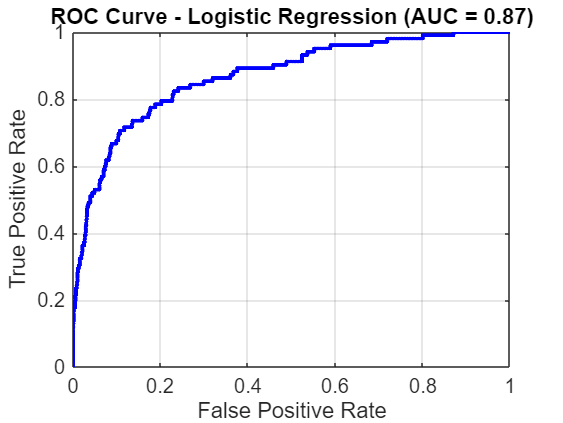


% ROC Curve
X_test_bias = [ones(size(X_test, 1), 1), X_test];
probs_log = sigmoid(X_test_bias * theta);

% Compute ROC
[Xroc, Yroc, T, AUC] = perfcurve(y_test, probs_log, 1);

% Plot ROC
figure;
plot(Xroc, Yroc, 'b-', 'LineWidth', 2);
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(['ROC Curve - Logistic Regression (AUC = ', num2str(AUC, '%.2f'), ')']);
grid on;

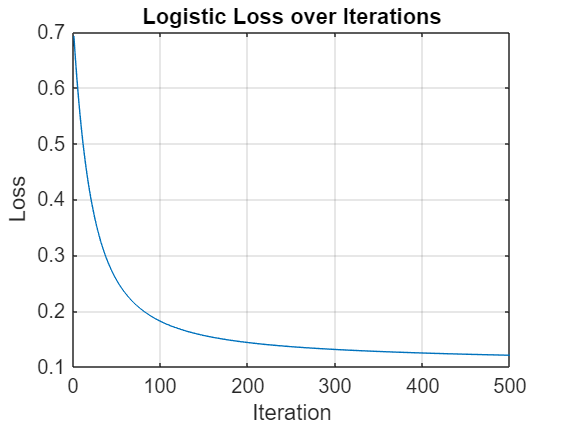

% Loss Curve Visualization
figure; 
plot(loss_hist); 
title('Logistic Loss over Iterations');
xlabel('Iteration'); 
ylabel('Loss');
grid on;

**Naive Bayes**

% Naive Bayes
disp('Naive Bayes');

Naive Bayes


function model = train_naive_bayes(X, y)
    classes = unique(y);
    model.classes = classes;
    model.priors = zeros(length(classes),1);
    model.mu = zeros(length(classes), size(X,2));
    model.sigma = zeros(length(classes), size(X,2));

    for i = 1:length(classes)
        X_c = X(y == classes(i), :);
        model.priors(i) = size(X_c, 1) / size(X, 1);
        model.mu(i, :) = mean(X_c);
        model.sigma(i, :) = std(X_c) + 1e-6;
    end
end

% Naive Bayes Prediction (with probabilities)
function [y_pred, probs] = predict_naive_bayes(X, model)
    n = size(X,1);
    log_probs = zeros(n, length(model.classes));
    
    for i = 1:length(model.classes)
        mu = model.mu(i,:);
        sigma = model.sigma(i,:);
        log_prior = log(model.priors(i));
        
        % Gaussian log likelihood
        log_likelihood = -0.5 * sum(log(2*pi*sigma.^2)) ...
                         -0.5 * sum(((X - mu).^2) ./ (sigma.^2), 2);
        
        log_probs(:,i) = log_prior + log_likelihood;
    end

    % Softmax-style normalization for numeric stability
    probs_matrix = exp(log_probs);
    probs = probs_matrix(:,2) ./ sum(probs_matrix, 2);  % Probability of class 1

    [~, max_idx] = max(log_probs, [], 2);
    y_pred = model.classes(max_idx);
end

% Train Naive Bayes
model_nb = train_naive_bayes(X_train, y_train);
[y_pred_nb, probs_nb] = predict_naive_bayes(X_test, model_nb);

% Confusion Matrix
C = confusionmat(y_test, y_pred_nb);
disp('Confusion Matrix:');

Confusion Matrix:


disp(C);

        2837          61
          63          39




% Accuracy
accuracy = sum(y_pred_nb == y_test) / numel(y_test);
fprintf('Test Accuracy (Naive Bayes): %.2f%%\n\n\n', accuracy * 100);

Test Accuracy (Naive Bayes): 95.87%




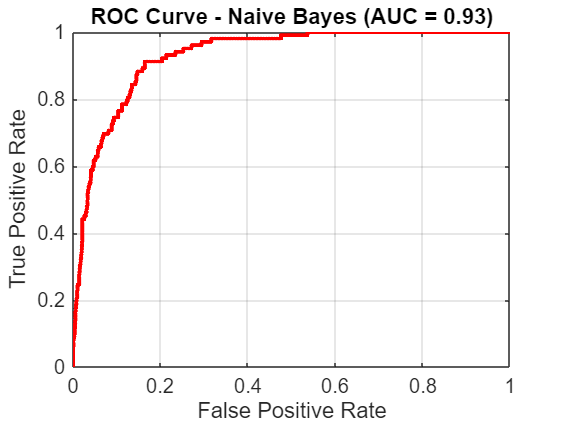


% ROC Curve
[Xroc, Yroc, T, AUC] = perfcurve(y_test, probs_nb, 1);

figure;
plot(Xroc, Yroc, 'r-', 'LineWidth', 2);
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(['ROC Curve - Naive Bayes (AUC = ', num2str(AUC, '%.2f'), ')']);
grid on;